# Computing spectra for RGB LEDs for any operating conditions, using information from data sheet.

clear;
% read spectrum, sampled from data sheet or from vendor web site (as part of ray file)
blue = ReadLightToolsSpectrumFile('blue.sre');
T_group = 25;
I_group = 350;
% create LED data structure
blueLED = RGBLEDSpectrum(blue, 25, 350);
% characteristic curves sampled from data sheet
I_vs_U = struct('U',[2.53,2.6,2.7,2.8,2.9,3.0,3.111],'I',[30,78,184,333,516,723,1000]);
relFlux_vs_I = struct('I',[30,100,200,350,400,600,800,1000],...
    'relFlux',[0.128,0.374,0.648,1.0,1.1,1.48,1.815,2.136]);
relFlux_vs_Temp = struct('Temp',[-40,-10,25,50,120],'relFlux',[0.975,0.975,1.0,1.04,1.205]);
delta_ldom_vs_I = struct('I',[30,100,200,350,500,700,1000],'delta_ldom',[3,1.6,0.75,0,-0.46,-0.9,-1.26]);
delta_ldom_vs_Temp = struct('Temp',[-40,-10,25,50,120],'delta_ldom',[-1.8,-1.1,0,1.1,4.8]);
deltaU_vs_Temp = struct('Temp',[-40,-10,25,50,120],'deltaU',[0.16,0.07,0,-0.048,-0.17]);
% set characteristic curves
blueLED.SetCharacteristicCurves(I_vs_U, relFlux_vs_I, relFlux_vs_Temp, delta_ldom_vs_I, ...
                delta_ldom_vs_Temp, deltaU_vs_Temp);

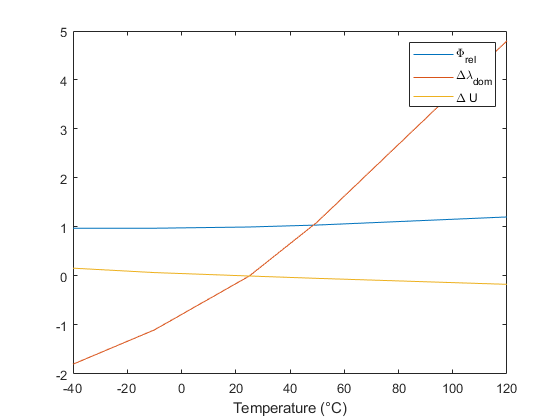

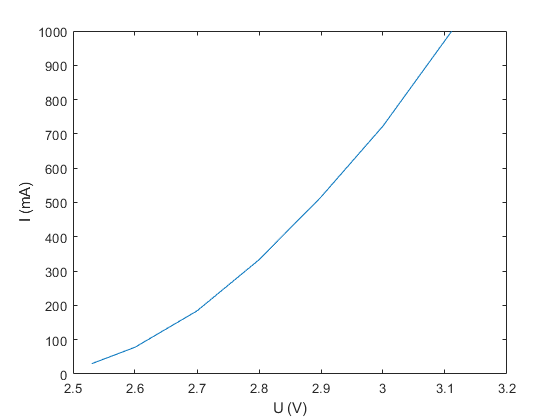

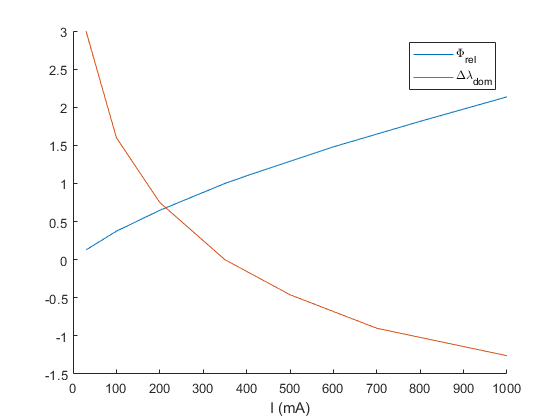

% see if characteristic curves are in good shape
blueLED.PlotCharacteristicCurves();

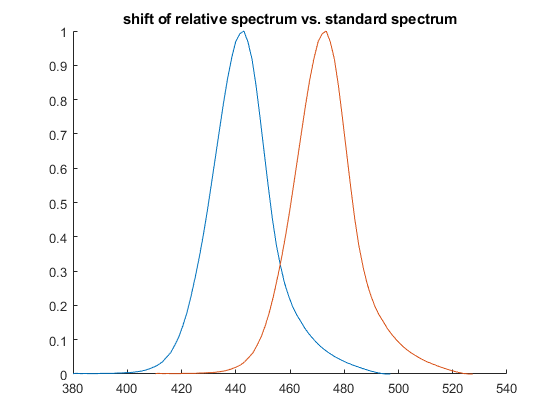

% Choose LED parameters, for a certain LED from a certain bin
U_binning = 2.9; %volt
Phiv_binning = 55; %lm
ldom_binning = 470; % dominant wavelength
% inform the data structure about these
blueLED.SetBinningParameters(U_binning,Phiv_binning,ldom_binning);
% compute the spectrum for arbitrary operating conditions
I_operating = 230; 
T_operating = 87;
spec = blueLED.OperatingSpectrum(I_operating, T_operating);
figure();
clf;
hold on;
plot(blue.lam, blue.val/max(blue.val));
plot(spec.lam, spec.val/max(spec.val));
title('shift of relative spectrum vs. standard spectrum');

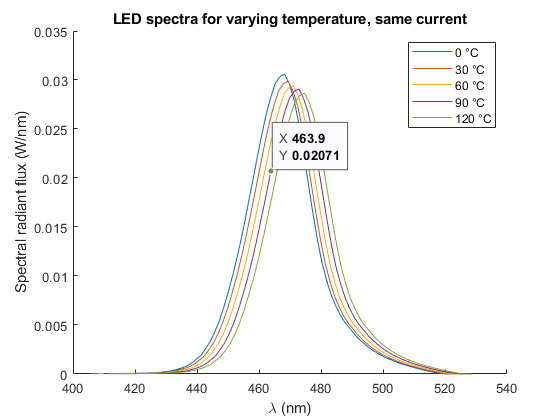


% plot spectra for varying temperature
% note that the radiant flux obviously decreases with temperature,
% which is both expected and consistent with the increase of luminous flux 
% with temperature: The wavelength shift moves the spectrum towards higher eye sensitivity
figure();
clf;
hold on;
i = 0;
for T = [0:30:120]
    spec = blueLED.OperatingSpectrum(350,T);
    plot(spec.lam, spec.val);
    i = i+1;
    legends{i} = sprintf('%g °C',T);
end
legend(legends);
title('LED spectra for varying temperature, same current')
xlabel('\lambda (nm)');
ylabel('Spectral radiant flux (W/nm)');

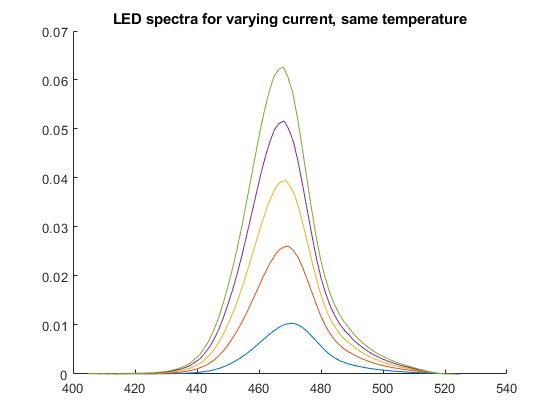


% plot spectra for varying current
% note the wavelength shift
figure();
clf;
hold on;
for I = [100:200:900]
    spec = blueLED.OperatingSpectrum(I,25);
    plot(spec.lam, spec.val);
end
title('LED spectra for varying current, same temperature')